 TrendTradingOptimSurrogate

Optimize sortino ratio

clear 

tic

rng(1,'twister') % For reproducibility

options = optimoptions ("surrogateopt", ...
    'PlotFcn',{"optimplotfval" ,"optimplotx", 'surrogateoptplot'});
options = optimoptions (options, "UseParallel",true, "Display","final", "ObjectiveLimit", -10)

options =   surrogateopt options:

   Set properties:
                   Display: 'final'
            ObjectiveLimit: -10
                   PlotFcn: {'optimplotfval'  'optimplotx'  'surrogateoptplot'}
               UseParallel: 1

   Default properties:
            CheckpointFile: []
       ConstraintTolerance: 1.0000e-03
             InitialPoints: []
    MaxFunctionEvaluations: 'max(200,50*numberOfVariables)'
                   MaxTime: Inf
         MinSampleDistance: 1.0000e-03
        MinSurrogatePoints: 'max(20,2*numberOfVariables)'
                 OutputFcn: []


Objective or constraint function returned NaN.


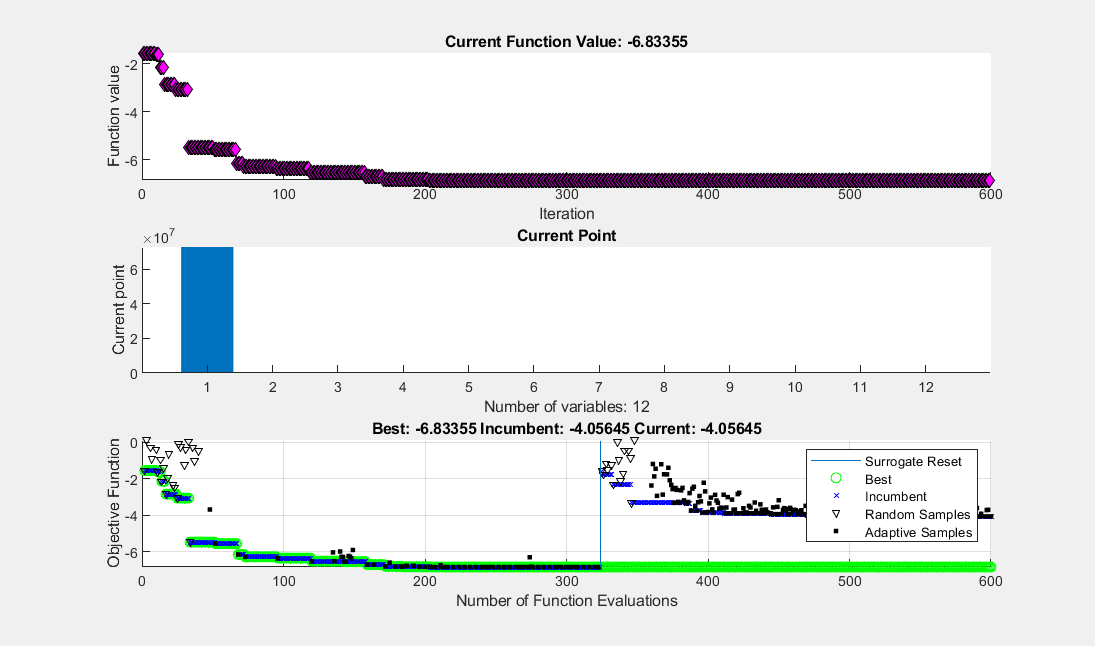

Surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


x =     73020124          24          25           1          15          12          67          50          21          25           1          73


fval = -6.8336

exitflag = 0

output = struct with fields:
        elapsedtime: 1.3466e+03
          funccount: 600
    constrviolation: 0
               ineq: [1×0 double]
           rngstate: [1×1 struct]
            message: 'Surrogateopt stopped because it exceeded the function evaluation limit set by ↵'options.MaxFunctionEvaluations'.'



FitnessFunction = @(x) TrendTradingFcnMultiVar(x) ;
nvars = 12 ;
IntCon = 1: nvars ;
lb = [100, 1, -30, 1, 0, 0, 1, -20, 1, 1, -30, 1 ] ;
ub = [10^8, 90, 90, 90, 20, 20, 90, 90, 90, 90, 50, 90 ] ;
% xo = lb+rand(1)*(ub-lb) ;

[x, fval, exitflag, output] = surrogateopt (FitnessFunction, lb, ub, IntCon, options)

    
toc

Elapsed time is 1349.580841 seconds.


Ploting

MinValue = 73020124

MomContDays = 24

MomContRetTrheshold = 25

LowLiquidDays = 1

LowLiquidThreshold = 15

LiquidSurgThreshold = 12

MomMainDays = 67

MomMainRetThreshold = 50

PostSignalBufferDays = 21

StopLossLookbackWindSz = 25

StopLossThreshold = 1

MinNSymDivers = 73

ans = -0.0087

ans = 0.0102

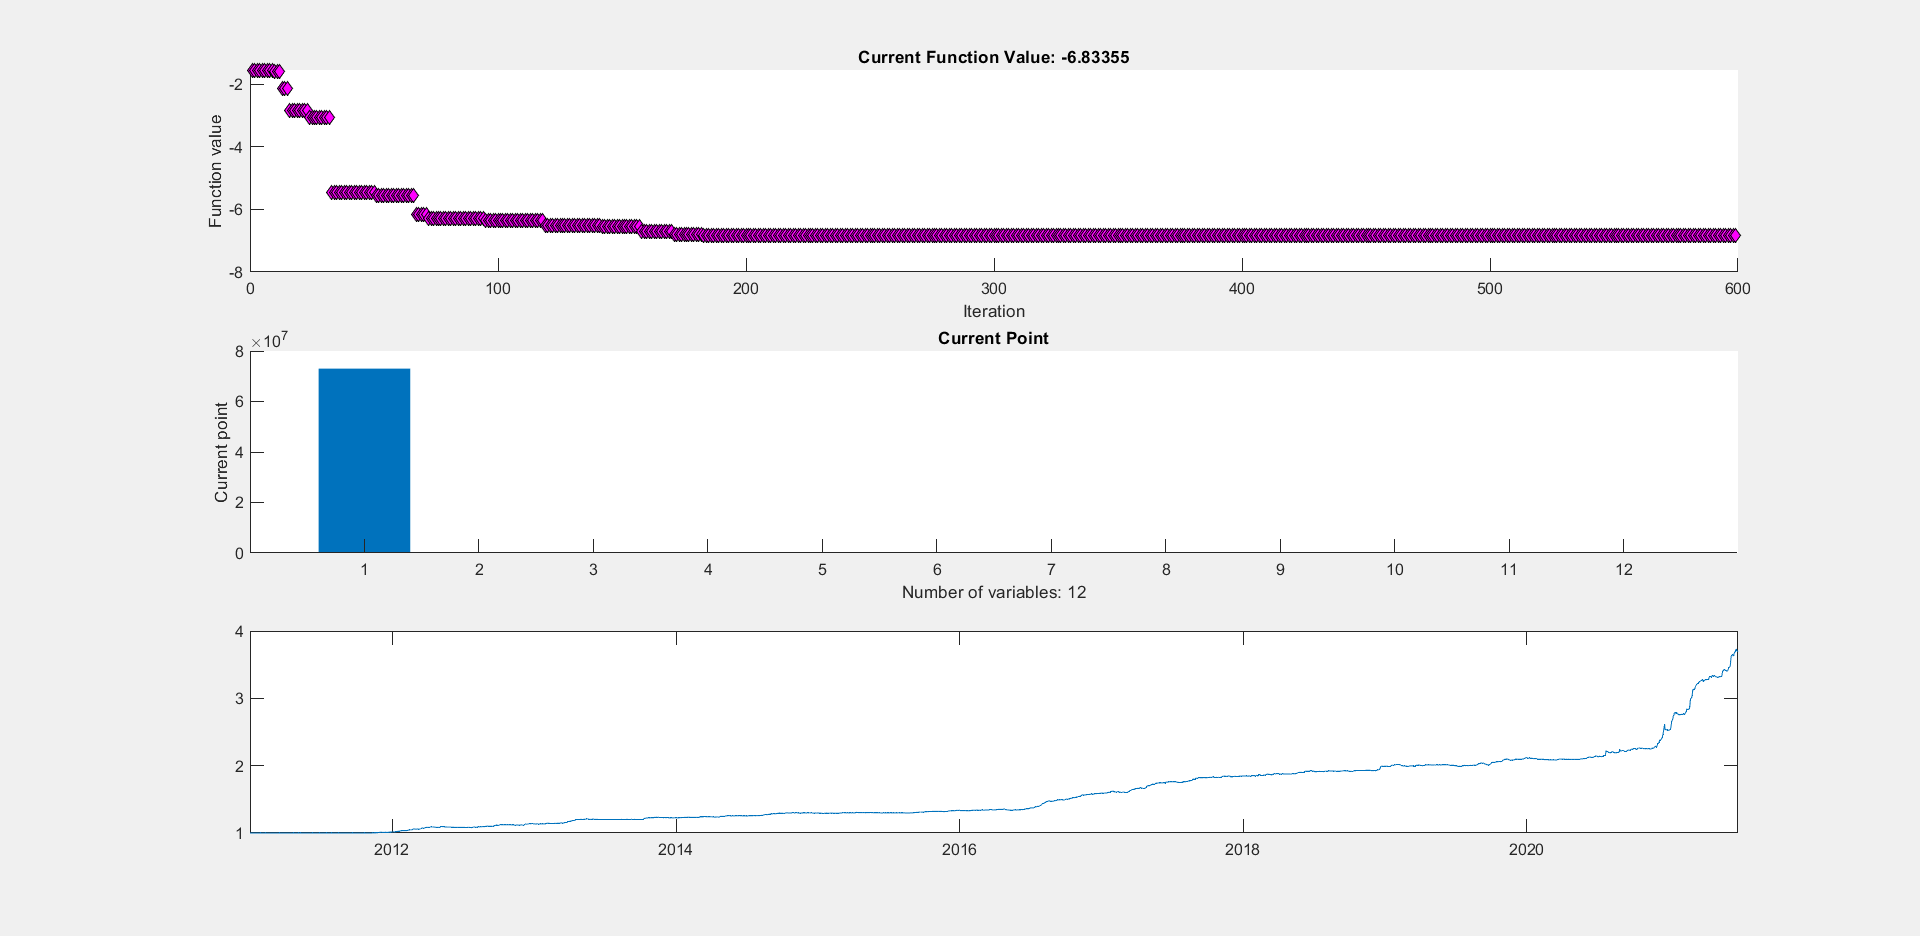

EndCumSum = 3.6932

TradingPeriod = 10.5014

CAGR = 0.1325

SharpeRatio = -3.1324

Sortino = -7.4826

Elapsed time is 4.295789 seconds.


y = -3.1324

y = TrendTradingFcnMultiVarV2 (x)